% Parameters
S0 = 100;     % Initial stock price
K = 100;      % Strike price
r = 0.02;     % Risk-free interest rate
sigma = 0.3;  % Volatility
T = 5 / 12;   % Time to maturity in years
Smax = 300;   % Maximum stock price in grid
M = 20;       % Number of stock price steps
N = 10;       % Number of time steps

% Discretization parameters
dS = Smax / M;
dt = T / N;

% Grid setup for stock price and option value
S = linspace(0, Smax, M+1)';    % Stock prices from 0 to Smax
f = zeros(M+1, N+1);            % Option values grid

% Terminal condition: payoff at maturity
f(:, end) = max(K - S, 0);

% Coefficients for the tridiagonal matrix
a = 0.5 * dt * (sigma^2 * (0:M-1)'.^2 - r * (0:M-1)');
b = 1 + dt * (sigma^2 * (0:M-1)'.^2 + r);
c = 0.5 * dt * (sigma^2 * (0:M-1)'.^2 + r);

% Construct the tridiagonal matrix
A = diag(b(2:M)) + diag(-a(3:M), -1) + diag(-c(2:M-1), 1);

% Boundary conditions: f(0, t) = K, f(Smax, t) = 0
for j = N:-1:1
    d = f(2:M, j+1);        % Right-hand side
    d(1) = d(1) + a(2) * K; % Apply boundary condition at S = 0
    d(end) = d(end);        % Boundary condition at S = Smax (no adjustment needed)
    
    % Solve the system A*f = d
    f(2:M, j) = A \ d;
    
    % American option condition (ensure option value >= intrinsic value)
    f(:, j) = max(f(:, j), K - S);
end

% Interpolate to find the option price at S0
put_price = interp1(S, f(:, 1), S0);

% Display the result
fprintf('The price of the American put option is: %.4f\n', put_price);

The price of the American put option is: 7.6920


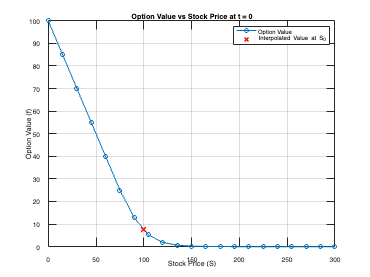


% Interpolate to find the option value at S0 for each time step
option_values = interp1(S, f, S0);

% Plot the option value at t = 0 and the interpolated price at S0
figure;
plot(S, f(:, 1), '-o', 'LineWidth', 1.5);
hold on;
plot(S0, put_price, 'rx', 'MarkerSize', 10, 'LineWidth', 2); % Interpolated point at S0
title('Option Value vs Stock Price at t = 0');
xlabel('Stock Price (S)');
ylabel('Option Value (f)');
legend('Option Value', 'Interpolated Value at S_0');
grid on;
hold off;